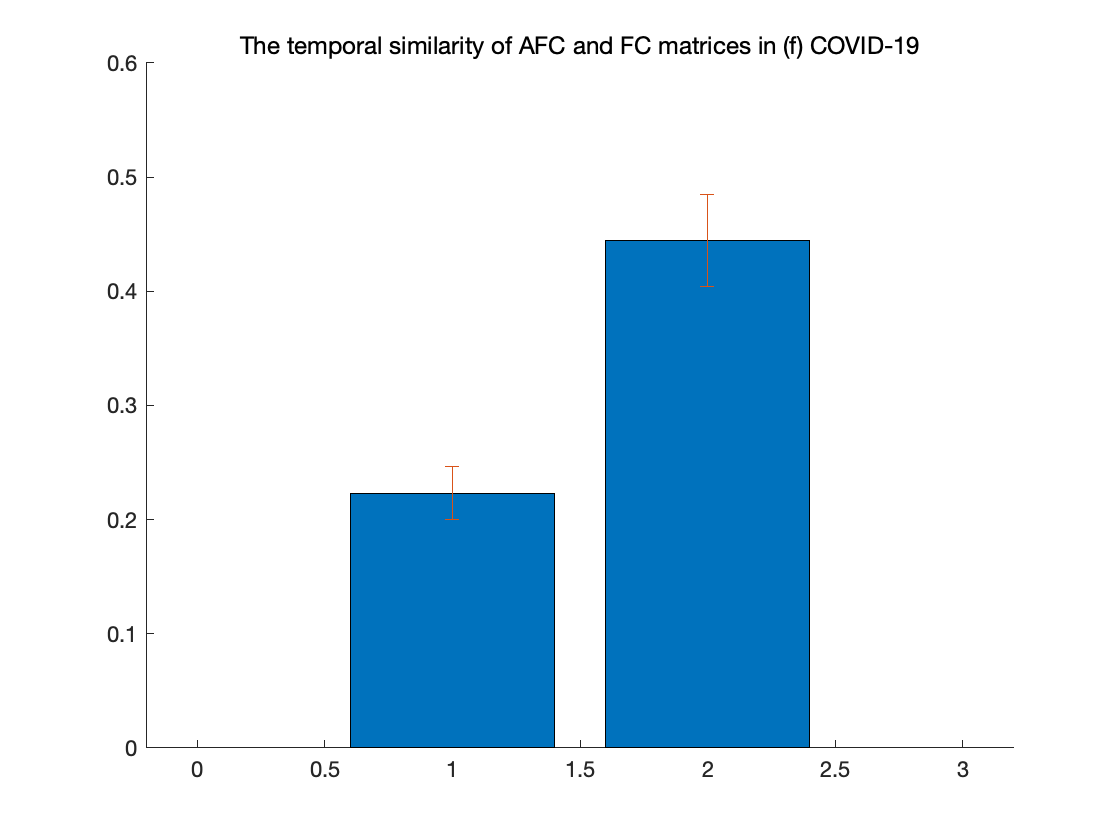

clear
clc
warning off

load sub_network_label.mat
load label_ind.mat

label = label_ind(:, 2);
label_NC = find(label == 0);

load mean_p.mat


% plot temporal similarity
figure
hold on
bar(mean(p(label_NC, :)))
errorbar(mean(p(label_NC, :)), std(p(label_NC, :)), 'LineStyle', 'none')
ylim([0 0.6])
title('The temporal similarity of AFC and FC matrices in (f) COVID-19')


[H,P,CI,STATS] = ttest2(p(label_NC, 1), p(label_NC, 2))

H = single
1

P = single
0

CI = 2×1 single 列向量
   -0.2264
   -0.2161


STATS = 包含以下字段的 struct :
    tstat: -84.6041
       df: 626
       sd: 0.0328



if P < 0.001
    disp("Significant difference: p < 0.001")
elseif p < 0.05 & p > 0.001
    disp("Significant difference: p < 0.05")
end

Significant difference: p < 0.001


clear
clc

load label_ind.mat

label = label_ind(:, 2);
label_NC = find(label == 0);

% 1 is the COVID-19 patient

load Data_graph.mat
 


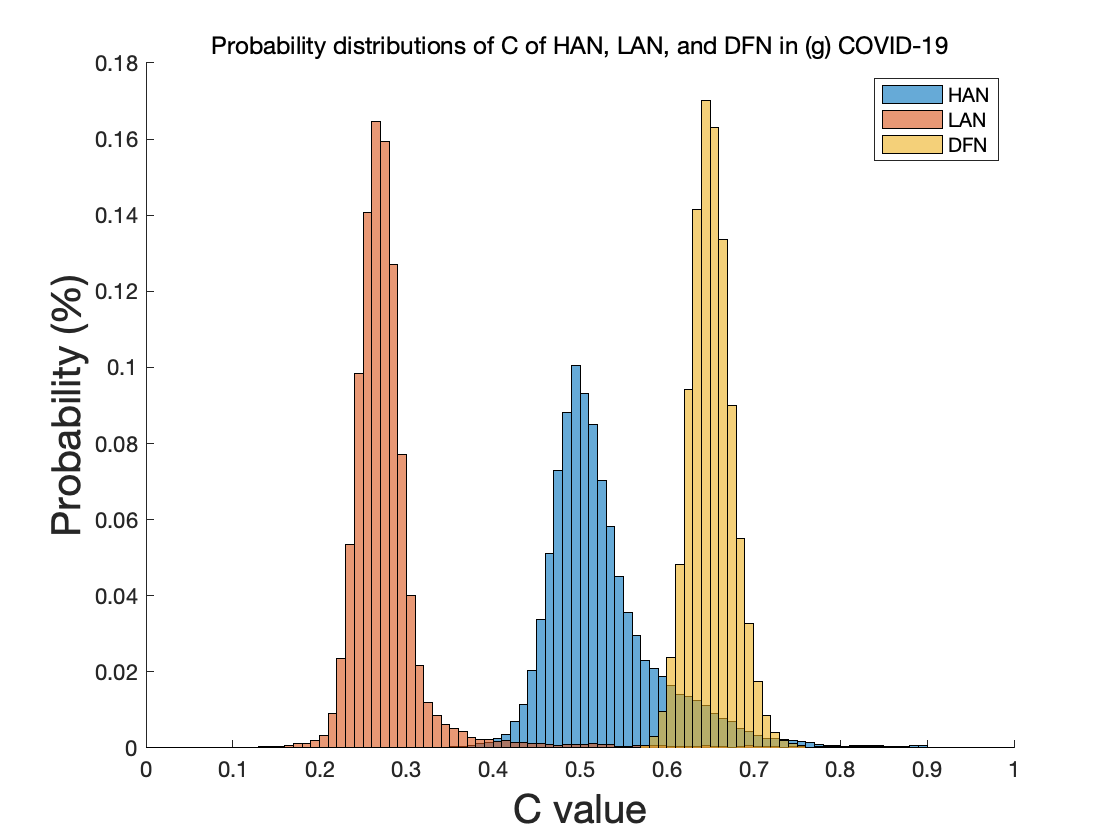

% plot C

data_NC = C(label_NC, :, :);
data_NC_mean = squeeze(mean(C(label_NC, :, :), 2));
data_NC_std = squeeze(std(C(label_NC, :, :), [], 2));
data_NC = reshape(data_NC, [size(data_NC, 1) * size(data_NC, 2), 3]);


% plot distribution
figure
hold on

for i = 1:3
data = data_NC(:, i);
data = data(:);

binWidth = 0.01;
lastVal = 1;
binEdges = 0:binWidth:lastVal;
h = histogram(data,binEdges, 'Normalization', "probability");
xlabel('C value', "FontSize", 20);
ylabel('Probability (%)', "FontSize", 20);
xlim([0 1])
end
title('Probability distributions of C of HAN, LAN, and DFN in (g) COVID-19')
legend({'HAN', 'LAN', 'DFN'})

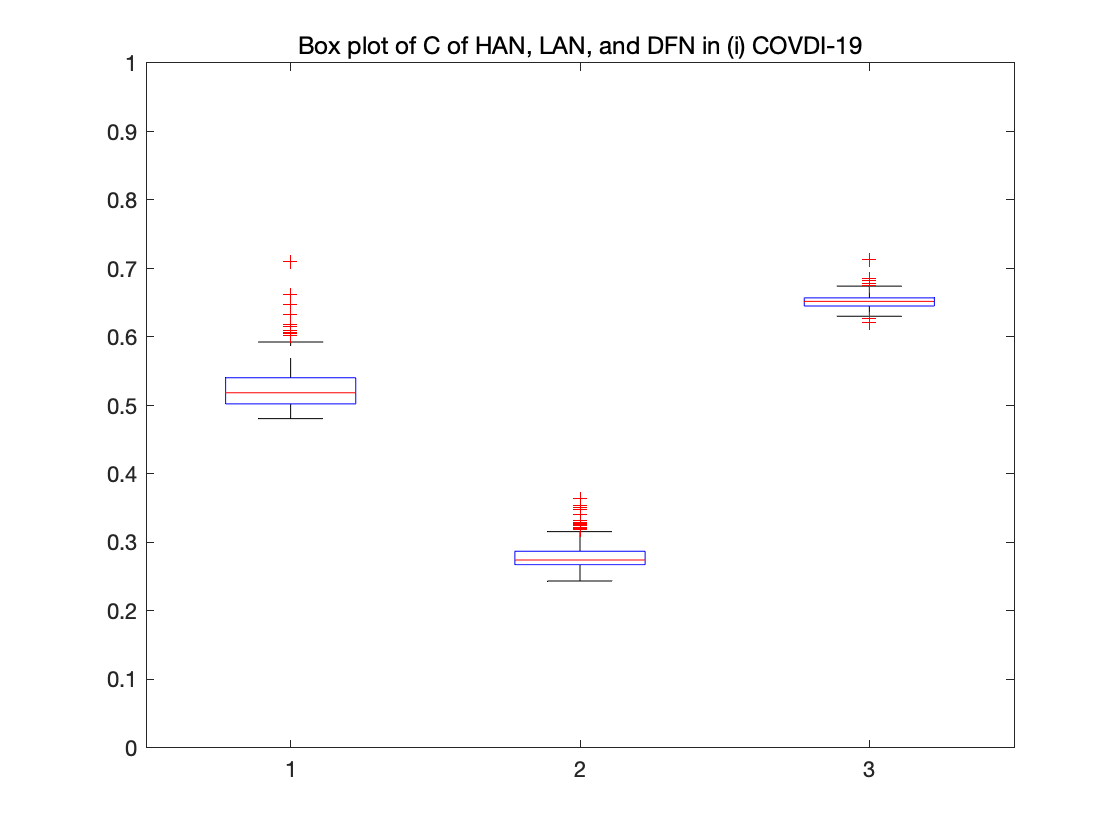



% box plot
figure
boxplot(data_NC_mean)
ylim([0 1])
title('Box plot of C of HAN, LAN, and DFN in (i) COVDI-19')


[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 2));
p(1) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 3));
p(2) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 2), data_NC_mean(:, 3));
p(3) = P;

% fdr correct HAN, LAN, DFN
p = mafdr(p, 'BHFDR', true)

p = 	1.0e+-276 *

         0    0.3067         0


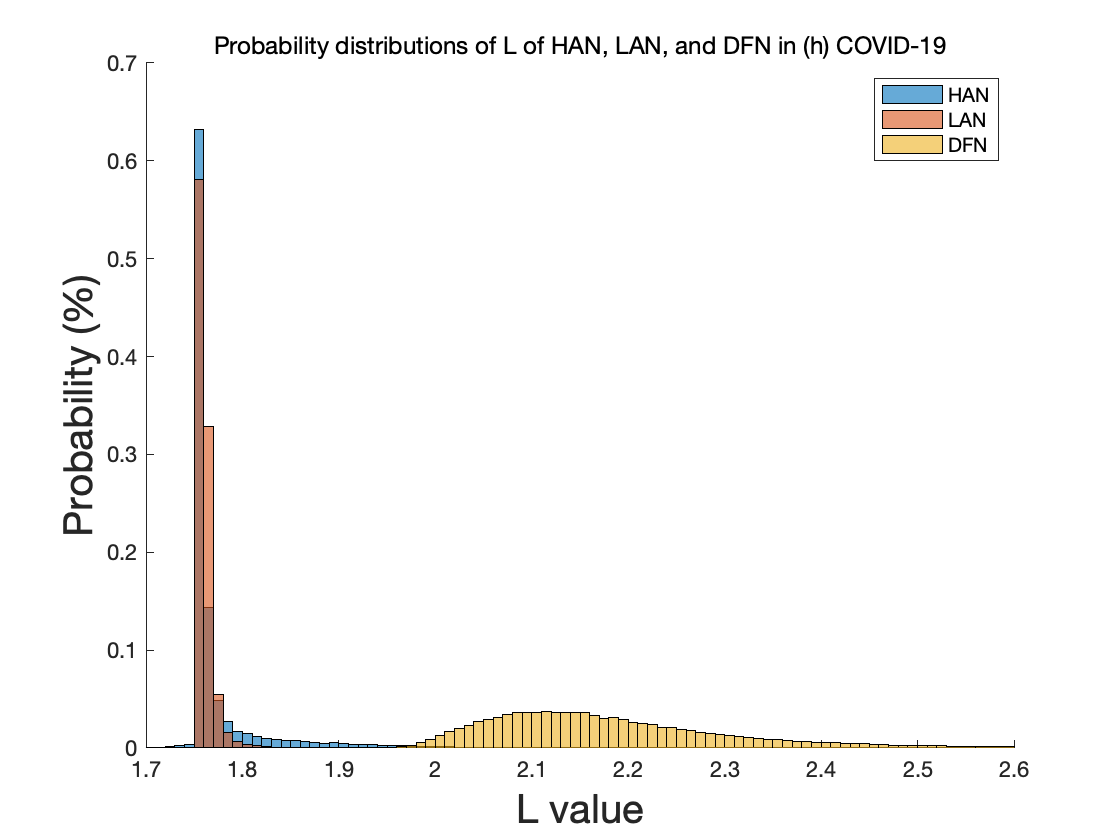

% plot L

data_NC = L(label_NC, :, :);
data_NC_mean = squeeze(mean(L(label_NC, :, :), 2));
data_NC_std = squeeze(std(L(label_NC, :, :), [], 2));
data_NC = reshape(data_NC, [size(data_NC, 1) * size(data_NC, 2), 3]);


% plot distribution
figure
hold on

for i = 1:3
data = data_NC(:, i);
data = data(:);

binWidth = 0.01;
lastVal = 2.6;
binEdges = 1.5:binWidth:lastVal;
h = histogram(data,binEdges, 'Normalization', "probability");
xlabel('L value', "FontSize", 20);
ylabel('Probability (%)', "FontSize", 20);
xlim([1.7 2.6])
end
title('Probability distributions of L of HAN, LAN, and DFN in (h) COVID-19')
legend({'HAN', 'LAN', 'DFN'})

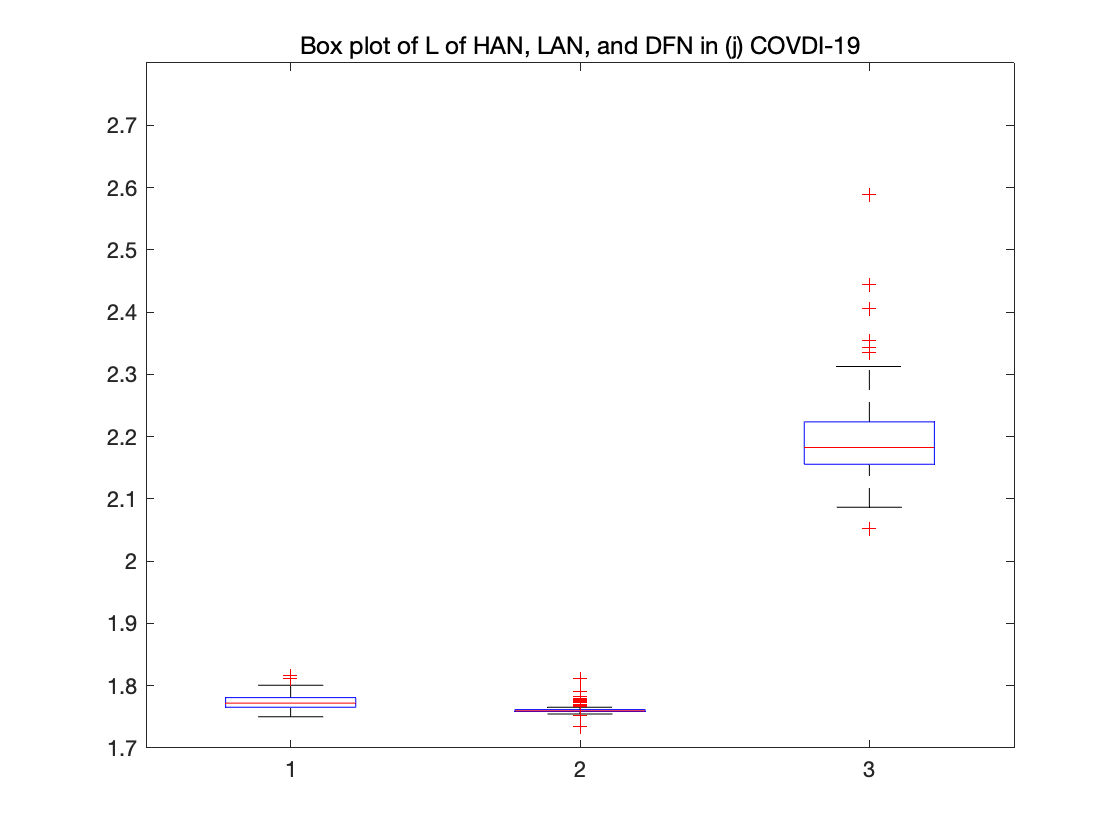



% box plot
figure
boxplot(data_NC_mean)
ylim([1.7 2.8])
title('Box plot of L of HAN, LAN, and DFN in (j) COVDI-19')


[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 2));
p(1) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 1), data_NC_mean(:, 3));
p(2) = P;

[H,P,CI,STATS] = ttest2(data_NC_mean(:, 2), data_NC_mean(:, 3));
p(3) = P;

% fdr correct HAN, LAN, DFN
p = mafdr(p, 'BHFDR', true)

p = 	1.0e+-61 *

    0.7589         0         0
